# **Curve Fitting and Derivative Estimation from Noisy Data**

This live script demonstrates robust curve fitting by utilizing neural networks to filter out noise without significant 

distortion. Additionally, the trained network is utilized to provide reliable and accurate derivative estimations.

## Curve Fitting of Noisy Data

### 1. Cost Function Selection

Mean square error is commonly used cost for various curve fitting problems, however,  MSE 

is sensitive to noise due to the squaring. 

Therefore, when dealing with extremely noisy data, **MAE** (Mean Absolute Error) is a more suitable metric.

(This rule also applied to n-dimensional surface fitting problems)

% Generate noisy signal using Van der Pol ODEs
clear; clc; close all;
[t,x] = ode45(@VanderPol,linspace(0,20,400),[2; 0]);
power=0.5; rng(1)
xNoisy=x+power*randn(size(x));
data=t'; label=xNoisy';

The noisy signal $\mathit{\mathbf{s}}$ are solutions of Van der Pol ODEs $\mathit{\mathbf{x}}:R\to R^2$ with Gaussian noise $\mathit{\mathbf{v}}\sim N\left(0,0\ldotp 5\right)$, i.e.


$$\begin{array}{l}
\frac{{\textrm{dx}}_1 }{\textrm{dt}}=x_2 \\
\frac{{\textrm{dx}}_2 }{\textrm{dt}}=\left(1-x_1^2 \right)x_2 -x_1 \\
\mathit{\mathbf{s}}\left(t\right)=\mathit{\mathbf{x}}\left(t\right)+\mathit{\mathbf{v}}\left(t\right)
\end{array}$$


### 2. Robust Curve Fitting using Neural Net

Using single neural net to fit the vector value function $\mathit{\mathbf{s}}\left(t\right):R\to R^2$. 

(you may also use 2 independent neural nets to fit $s_j \left(t\right):t\to s_j$)

NN.Cost='MAE'; NN.InputAutoScaling='on';
InputDimension=1; OutputDimension=2;
LayerStruct=[InputDimension,5,5,5,OutputDimension];
NN=Initialization(LayerStruct,NN);

Note that since neural networks are universal approximators, when dealing with extremely noisy data, 

one should not use a large network (**TOO FLEXIBLE**), in such case the networks will not only learn the underlying

pattern in the data, but also the noise.

option.MaxIteration=800;
NN=OptimizationSolver(data,label,NN,option);

Iteration : 10 , Cost :       2.54089589 
Iteration : 20 , Cost :       2.53966086 
Iteration : 30 , Cost :       2.53622140 
Iteration : 40 , Cost :       2.52772379 
Iteration : 50 , Cost :       2.51586369 
Iteration : 60 , Cost :       2.50784791 
Iteration : 70 , Cost :       2.50112020 
Iteration : 80 , Cost :       2.49529848 
Iteration : 90 , Cost :       2.48803416 
Iteration : 100 , Cost :       2.47703334 
Iteration : 110 , Cost :       2.45934697 
Iteration : 120 , Cost :       2.43591341 
Iteration : 130 , Cost :       2.41434813 
Iteration : 140 , Cost :       2.39191247 
Iteration : 150 , Cost :       2.36460411 
Iteration : 160 , Cost :       2.31532037 
Iteration : 170 , Cost :       2.23760141 
Iteration : 180 , Cost :       2.15762817 
Iteration : 190 , Cost :       2.09505748 
Iteration : 200 , Cost :       2.03376767 
------------------------------------------------------
First Stage Optimization Finished in  200  Iteration.
----------------------------------------

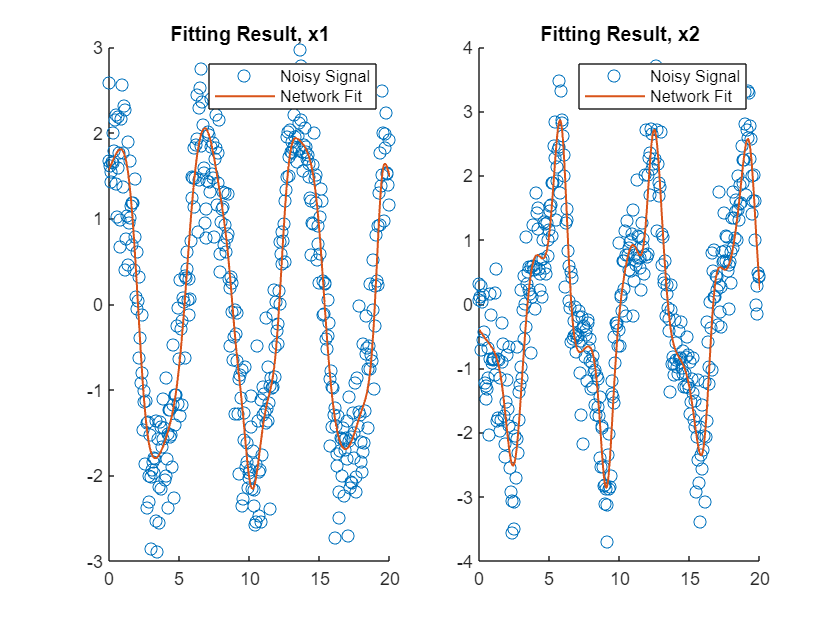

% Visualization
prediction=NN.Evaluate(data);
figure
subplot(1,2,1)
scatter(t,label(1,:)); hold on; plot(t,prediction(1,:),'LineWidth',1);
title('Fitting Result, x1')
legend('Noisy Signal','Network Fit')

subplot(1,2,2)
scatter(t,label(2,:)); hold on; plot(t,prediction(2,:),'LineWidth',1);
legend('Noisy Signal','Network Fit')
title('Fitting Result, x2')

## Derivative Estimation

### 1. Problems with Finite Difference

Derivatives are crucial information for many engineering problems. However, estimating derivatives directly from 

experimental data using finite differences can amplify the noise in the measurements, making the estimation unreliable. 

Let's try using forward differences to observe the effect.

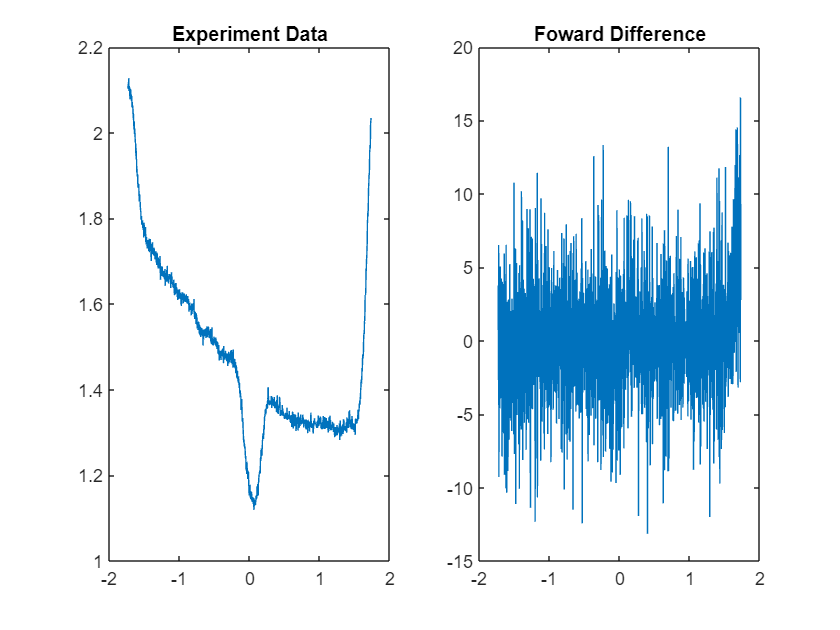

% Visualize data
clear; clc; close all;
load('Experiment.mat');
data0=Experiment.Data;
label0=Experiment.Label;
subplot(1,2,1)
plot(data0,label0)
title('Experiment Data')

dy=diff(label0); FDestimate=dy/(data0(2)-data0(1));
subplot(1,2,2)
plot(data0(1:end-1),FDestimate)
title('Foward Difference')

An alternative approach is to first smooth the data and then apply finite differences again. 

While this approach can effectively reduce noise, it is important to note that smoothing the data may also introduce distortion.

### 2. Denoising using Neural Networks

Curve fitting is another viable method,  in order to capture the essential patterns, 

the fitted curve must effectively filter out the noise without excessively smoothing the data, 

this is where neural networks come into play.

(For less noisy data, using MSE or SSE can better capture the subtle patterns in the data.)

% NN Set Up
NN0.Cost='SSE';
NN0.LabelAutoScaling='on';
InputDimension=1; OutputDimension=1;
LayerStruct=[InputDimension,8,8,10,OutputDimension];
NN0=Initialization(LayerStruct,NN0);
% Solver Set Up
option.MaxIteration=400;
NN=OptimizationSolver(data0,label0,NN0,option);

Iteration : 5 , Cost :    1073.02344946 
Iteration : 10 , Cost :     971.41283905 
Iteration : 15 , Cost :     549.72350728 
Iteration : 20 , Cost :     352.16353396 
Iteration : 25 , Cost :     321.78608994 
Iteration : 30 , Cost :     308.14693563 
Iteration : 35 , Cost :     257.12990895 
Iteration : 40 , Cost :     238.52916482 
Iteration : 45 , Cost :     228.64655283 
Iteration : 50 , Cost :     226.14558150 
Iteration : 55 , Cost :     219.11271329 
Iteration : 60 , Cost :     214.76388668 
Iteration : 65 , Cost :     211.50428341 
Iteration : 70 , Cost :     209.27643468 
Iteration : 75 , Cost :     207.17984691 
Iteration : 80 , Cost :     205.49654179 
Iteration : 85 , Cost :     202.64921058 
Iteration : 90 , Cost :     200.27032672 
Iteration : 95 , Cost :     198.65453594 
Iteration : 100 , Cost :     197.89108846 
------------------------------------------------------
First Stage Optimization Finished in  100  Iteration.
---------------------------------------------------

option.Solver='BFGS'; % use Quasi-Newton Solver for faster convergence
option.MaxIteration=600;
NN0=OptimizationSolver(data0,label0,NN0,option);

Iteration : 30 , Cost :      31.79808473 
Iteration : 60 , Cost :       4.76634574 
Iteration : 90 , Cost :       3.75138727 
Iteration : 120 , Cost :       3.05199444 
Iteration : 150 , Cost :       2.84227390 
Iteration : 180 , Cost :       2.75759961 
Iteration : 210 , Cost :       2.72086392 
Iteration : 240 , Cost :       2.69234317 
Iteration : 270 , Cost :       2.66786728 
Iteration : 300 , Cost :       2.61592457 
Iteration : 330 , Cost :       2.52968148 
Iteration : 360 , Cost :       2.48665047 
Iteration : 390 , Cost :       2.46484976 
Iteration : 420 , Cost :       2.45003619 
Iteration : 450 , Cost :       2.43126401 
Iteration : 480 , Cost :       2.41577478 
Iteration : 510 , Cost :       2.39840836 
Iteration : 540 , Cost :       2.38975007 
Iteration : 570 , Cost :       2.37954774 
Iteration : 600 , Cost :       2.37040230 
------------------------------------------------------
Max Iteration : 600 , Cost :       2.37040230 
Optimization Time :   3.6
Mean Absolute E

It can be observed that **neural networks are capable of **

**filtering out noise while preserving essential patterns in the data**.

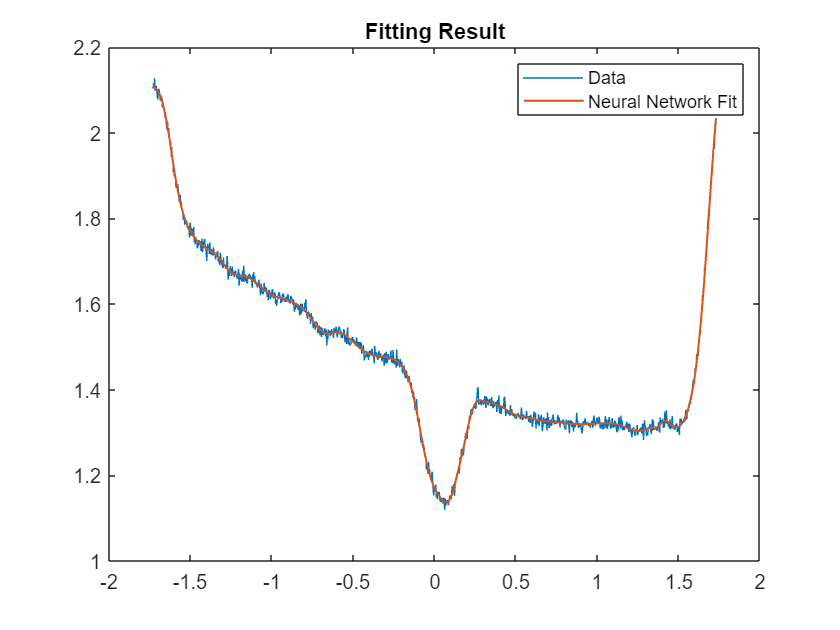

prediction0=NN0.Evaluate(data0);
figure
plot(data0,label0);hold on; plot(data0,prediction0,"LineWidth",1);
legend('Data','Neural Network Fit')
title('Fitting Result')

### 3. Computing Derivative of Neural Networks

Compute Derivative using `NN.Derivate `function.

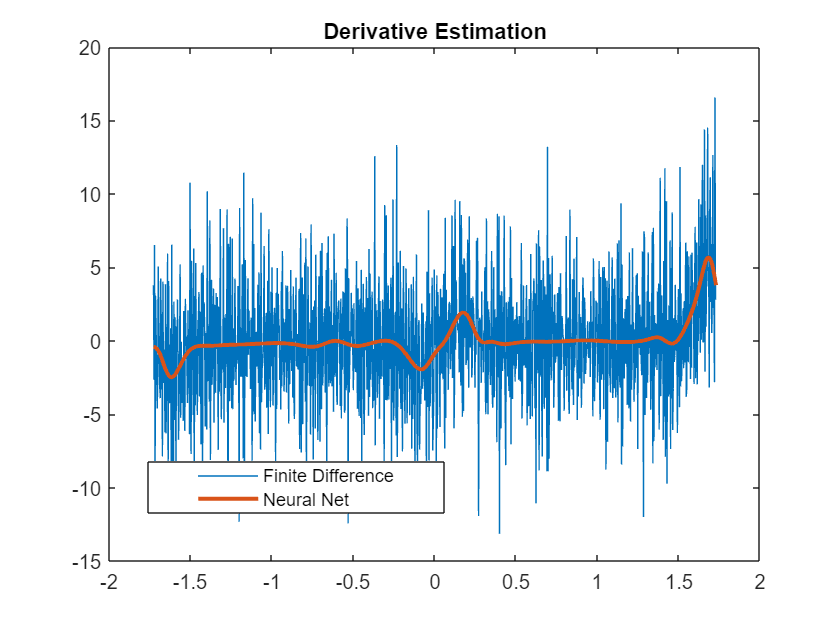

NNestimate=NN.Derivate(data0(1:end-1));
% Compare with Finite Difference
figure
plot(data0(1:end-1),FDestimate);
hold on
plot(data0(1:end-1),NNestimate,"LineWidth",2)
legend('Finite Difference','Neural Net')
legend("Position", [0.17655,0.18611,0.35357,0.082143])
title('Derivative Estimation')

Note that the functionality of `NN.Derivate` is to compute $\frac{\partial \textrm{NN}}{\partial \mathit{\mathbf{x}}}$, not $\frac{\partial \textrm{NN}}{\partial \;\mathit{\mathbf{W}}},\frac{\partial \textrm{NN}}{\partial \;\mathit{\mathbf{b}}}$)

The function "`NN.Derivate`" implements the complex step algorithm for calculating derivatives and

can be extended to multivariable functions $\textrm{NN}\left(\mathit{\mathbf{x}}\right):R^n \to R^m$ as well. 

i.e. Jacobian (if $m=1$, then $\mathit{\mathbf{J}}$ became gradient of $\mathit{\mathbf{f}}$)


$$\textrm{NN}\left(\mathit{\mathbf{x}}\right):R^n \to R^m ,\mathit{\mathbf{J}}\left(\mathit{\mathbf{x}}\right)=\left\lbrack \begin{array}{ccc}
\frac{\partial \;{\textrm{NN}}_1 }{\partial x_1 } & \cdots  & \frac{\partial \;{\textrm{NN}}_1 }{\partial x_n }\\
\vdots  & \ddots  & \vdots \\
\frac{\partial \;{\textrm{NN}}_m }{\partial x_2 } & \cdots  & \frac{\partial \;{\textrm{NN}}_m }{\partial x_n }
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\nabla {\textrm{NN}}_1 }^T \\
\vdots \\
{\nabla {\textrm{NN}}_m }^T 
\end{array}\right\rbrack$$


like most commands in MATLAB, "`NN.Derivate"` supprot matrix input, given a $N\times p$ matrix, where $p$ is number of input data points,

the function will output a $n\times p\times m$ matirx $\mathit{\mathbf{D}}$, and $\mathit{\mathbf{D}}\left(:,:,k\right)$ represent gradient of ${\textrm{NN}}_k \left(\mathit{\mathbf{x}}\right)$ evaluate at each given point ${\mathit{\mathbf{x}}}_j$.


$$\mathit{\mathbf{D}}\left(:,:,k\right)=\left\lbrack \begin{array}{cccc}
\nabla {\textrm{NN}}_k \left({\mathit{\mathbf{x}}}_1 \right) & \nabla {\textrm{NN}}_k \left({\mathit{\mathbf{x}}}_2 \right) & \cdots  & \nabla {\textrm{NN}}_k \left({\mathit{\mathbf{x}}}_p \right)
\end{array}\right\rbrack ,\nabla {\textrm{NN}}_k \left({\mathit{\mathbf{x}}}_j \right)\in R^{n\times 1}$$


With the ability to compute the derivatives of neural networks, we can apply them to various fields such as 

Surrogate Optimization and solving PDEs using neural nets (Physical-Informed Neural Networks, PINN). 

function dx=VanderPol(t,x)
dx=[x(2); (1-x(1)^2)*x(2)-x(1)];
end